%file paths of the gauges
path1 = "C:\Users\ericm\Dropbox\EAS 8803\Project 1\Sensor Data\Tokyo III.xlsx";
path2 = "C:\Users\ericm\Dropbox\EAS 8803\Project 1\Sensor Data\Aburatsumo.xlsx";
path3 = "C:\Users\ericm\Dropbox\EAS 8803\Project 1\Sensor Data\Ito II.xlsx";
path4 = "C:\Users\ericm\Dropbox\EAS 8803\Project 1\Sensor Data\Uchiura.xlsx";
path5 = "C:\Users\ericm\Dropbox\EAS 8803\Project 1\Sensor Data\Onisaki.xlsx";
path6 = "C:\Users\ericm\Dropbox\EAS 8803\Project 1\Sensor Data\Osaka.xlsx";

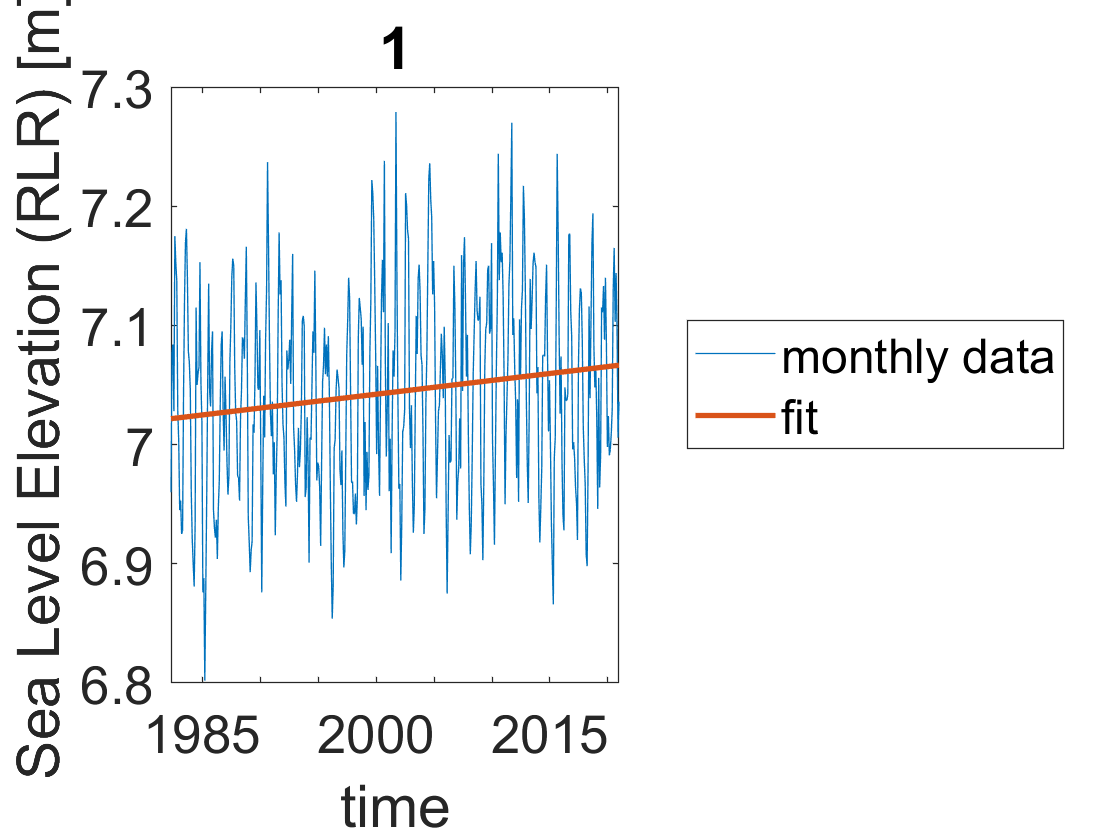

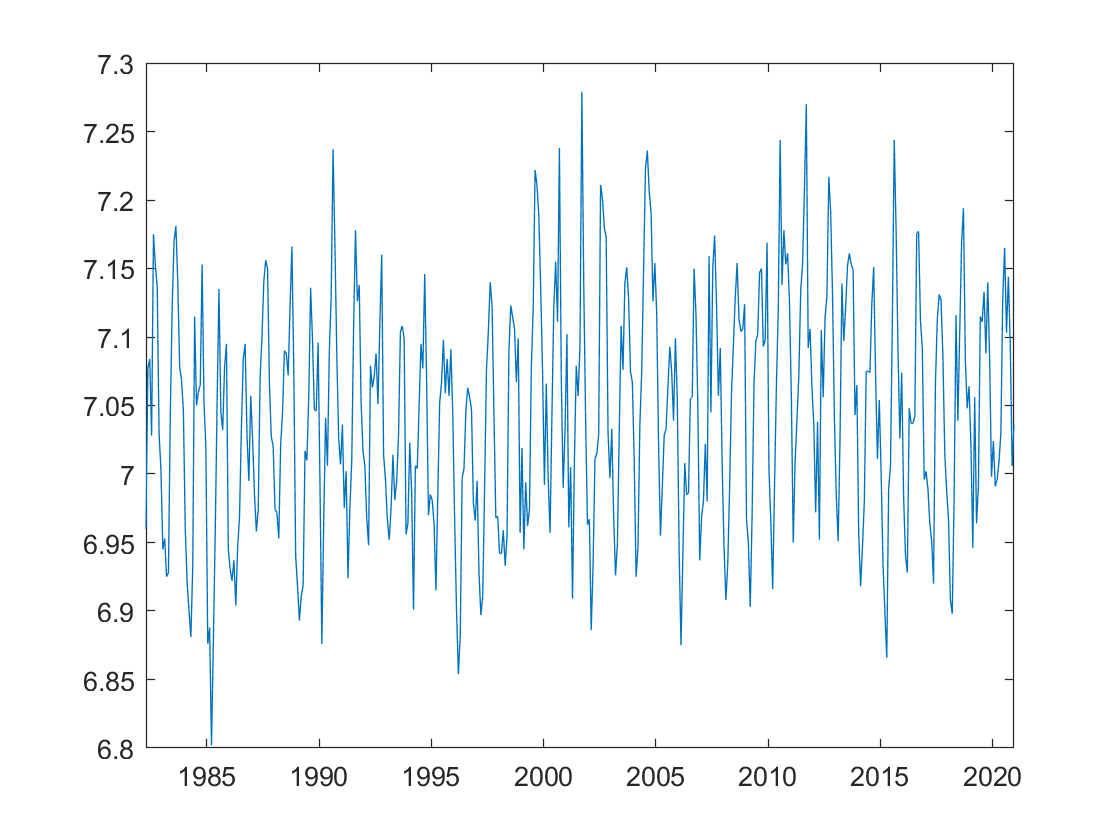

%1. Tokyo III
[date1, SL1] = readGauge(path1);

%%linear regression
num1 = datenum(date1);
A1(:, 1) = (num1 - num1(1))/365;
A1(:, 2) = 1;
regsol1 = A1\SL1;
linreg1 = regsol1(1).*A1(:, 1) + regsol1(2);

plot(date1, SL1)
hold on
plot(date1, linreg1, 'LineWidth', 2)
set(gca, 'fontsize', 20)
xlabel('time')
ylabel('Sea Level Elevation (RLR) [m]')
title('1')
legend('monthly data', 'fit', 'location', 'eastoutside')
hold off


%slope of regression [cm/y]
regsol1(1)*100

ans = 0.1159

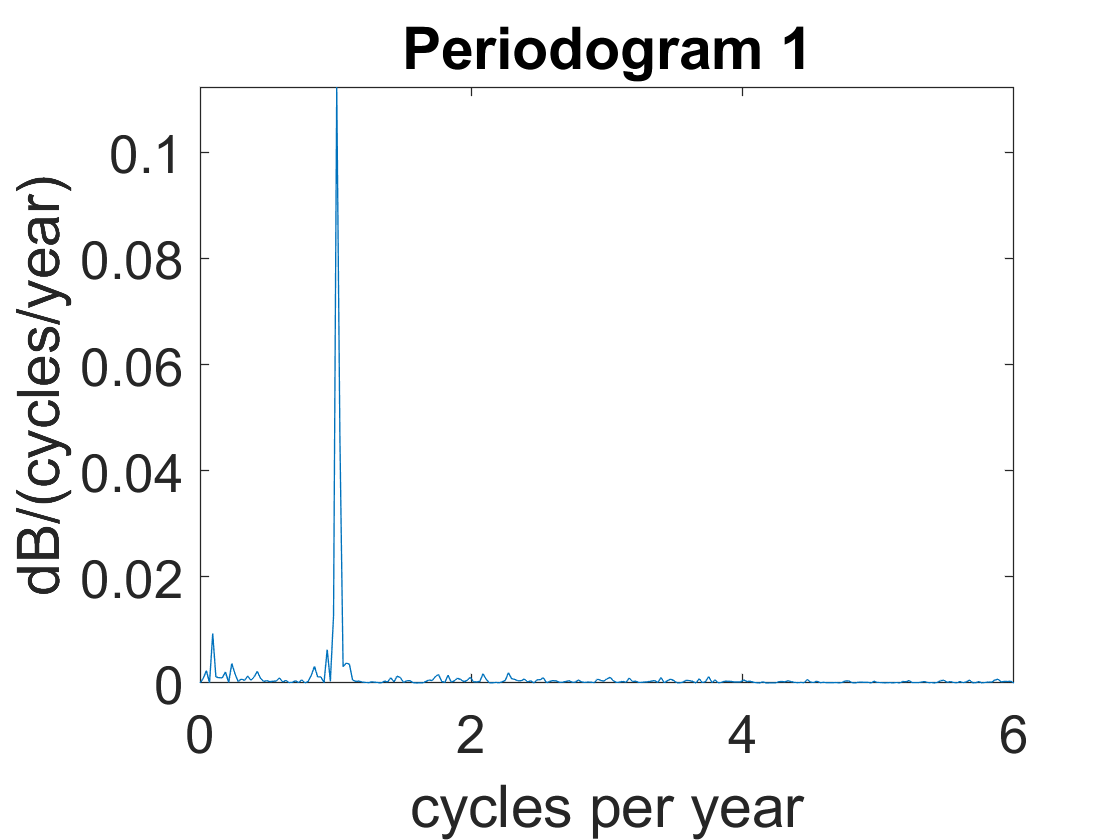


%%periodogram
%normalize data from trend
SL_noSLR1 = SL1 - linreg1;

%PSD calcs
[pxx1, f1] = periodogram(SL_noSLR1, [], [], 12);

plot(f1, pxx1)
set(gca, 'fontsize', 20)
title('Periodogram 1')
xlabel('cycles per year')
ylabel('dB/(cycles/year)')

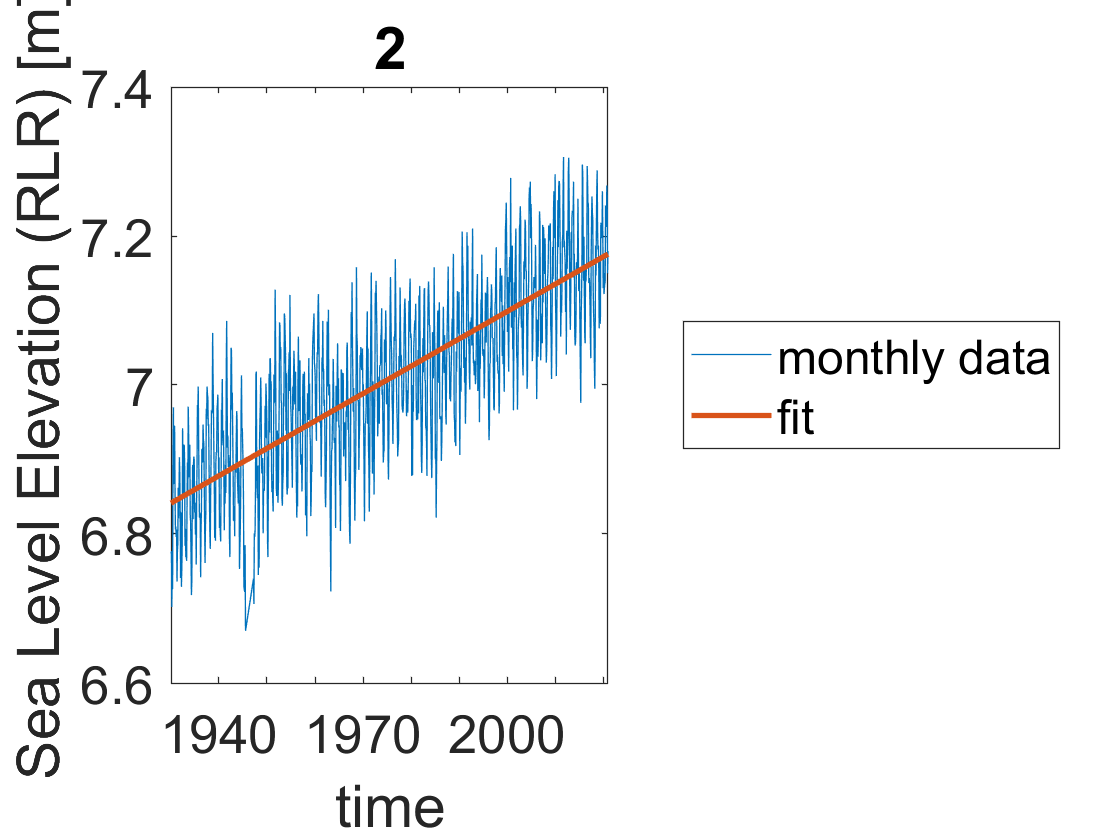

%2. Aburatsumo
[date2, SL2] = readGauge(path2);

%%linear regression
num2 = datenum(date2);
A2(:, 1) = (num2 - num2(1))/365;
A2(:, 2) = 1;
regsol2 = A2\SL2;
linreg2 = regsol2(1).*A2(:, 1) + regsol2(2);

plot(date2, SL2)
hold on
plot(date2, linreg2, 'LineWidth', 2)
set(gca, 'fontsize', 20)
xlabel('time')
ylabel('Sea Level Elevation (RLR) [m]')
title('2')
legend('monthly data', 'fit', 'location', 'eastoutside')
hold off


%slope of regression [cm/y]
regsol2(1)*100

ans = 0.3675

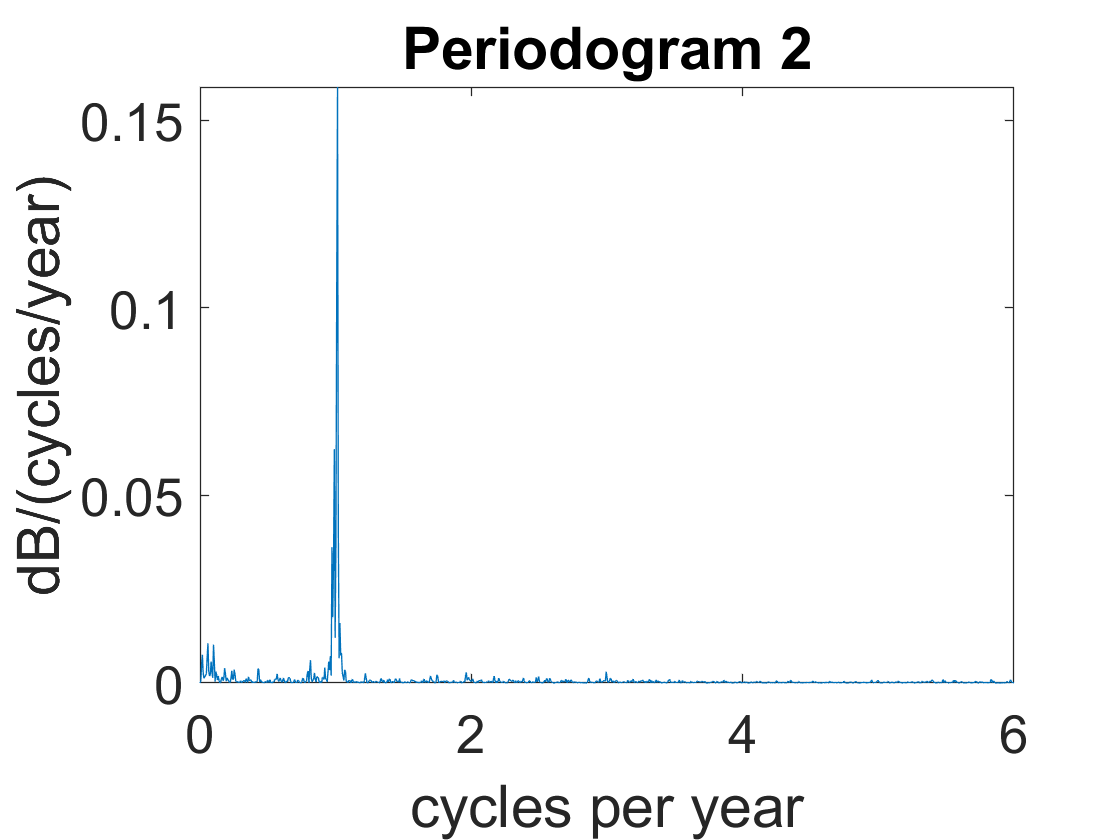


%%periodogram
%normalize data from trend
SL_noSLR2 = SL2 - linreg2;

%PSD calcs
[pxx2, f2] = periodogram(SL_noSLR2, [], [], 12);

plot(f2, pxx2)
set(gca, 'fontsize', 20)
title('Periodogram 2')
xlabel('cycles per year')
ylabel('dB/(cycles/year)')

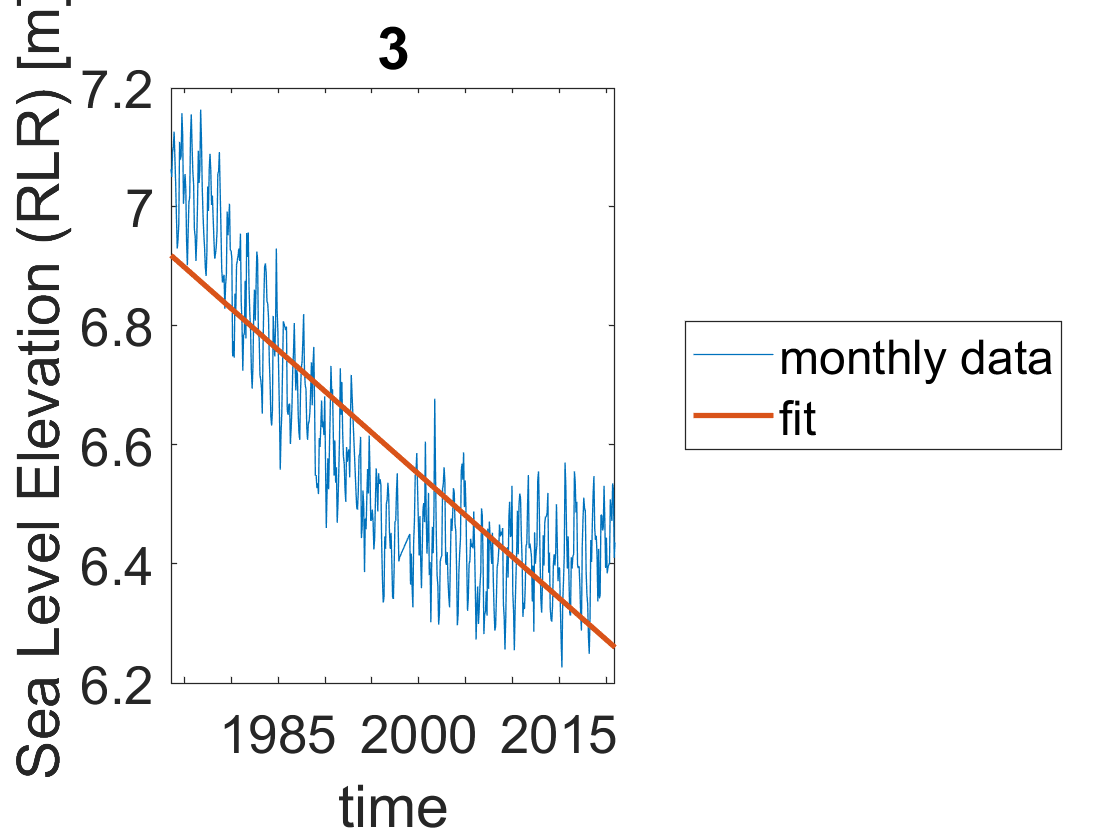

%3. Ito II
[date3, SL3] = readGauge(path3);

%%linear regression
num3 = datenum(date3);
A3(:, 1) = (num3 - num3(1))/365;
A3(:, 2) = 1;
regsol3 = A3\SL3;
linreg3 = regsol3(1).*A3(:, 1) + regsol3(2);

plot(date3, SL3)
hold on
plot(date3, linreg3, 'LineWidth', 2)
set(gca, 'fontsize', 20)
xlabel('time')
ylabel('Sea Level Elevation (RLR) [m]')
title('3')
legend('monthly data', 'fit', 'location', 'eastoutside')
hold off


%slope of regression [cm/y]
regsol3(1)*100

ans = -1.3863

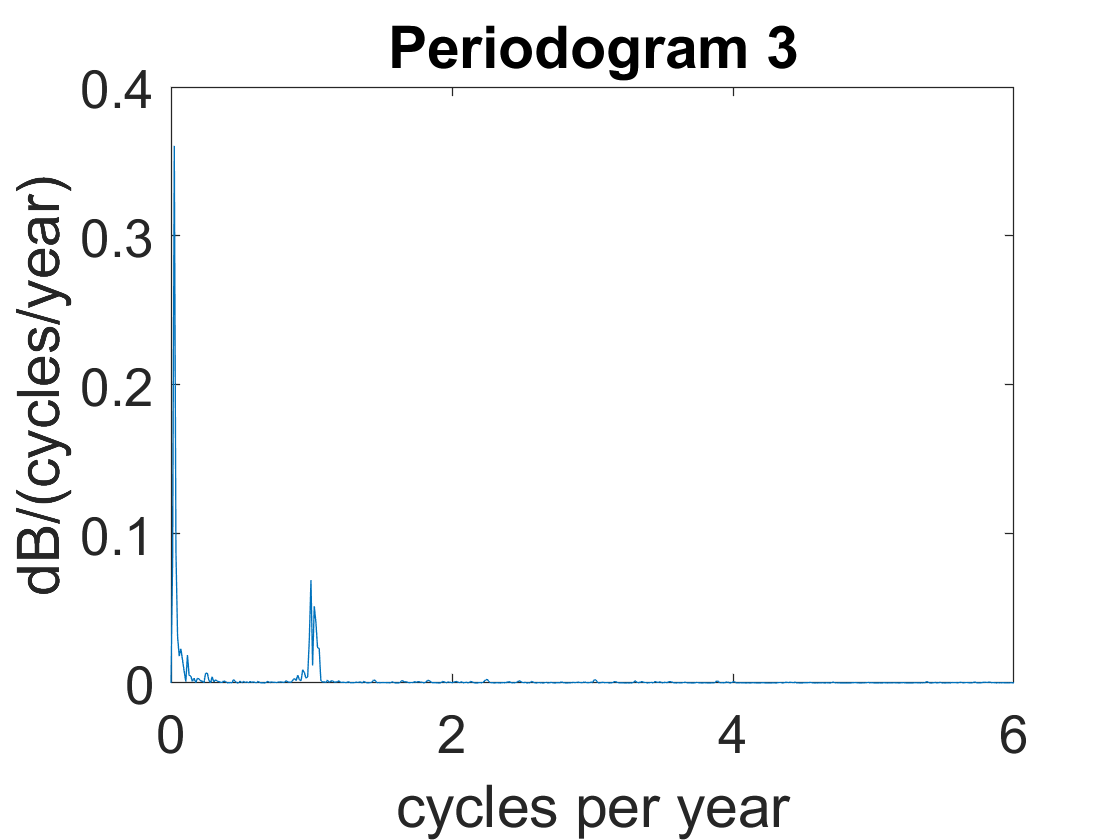


%%periodogram
%normalize data from trend
SL_noSLR3 = SL3 - linreg3;

%PSD calcs
[pxx3, f3] = periodogram(SL_noSLR3, [], [], 12);

plot(f3, pxx3)
set(gca, 'fontsize', 20)
title('Periodogram 3')
xlabel('cycles per year')
ylabel('dB/(cycles/year)')

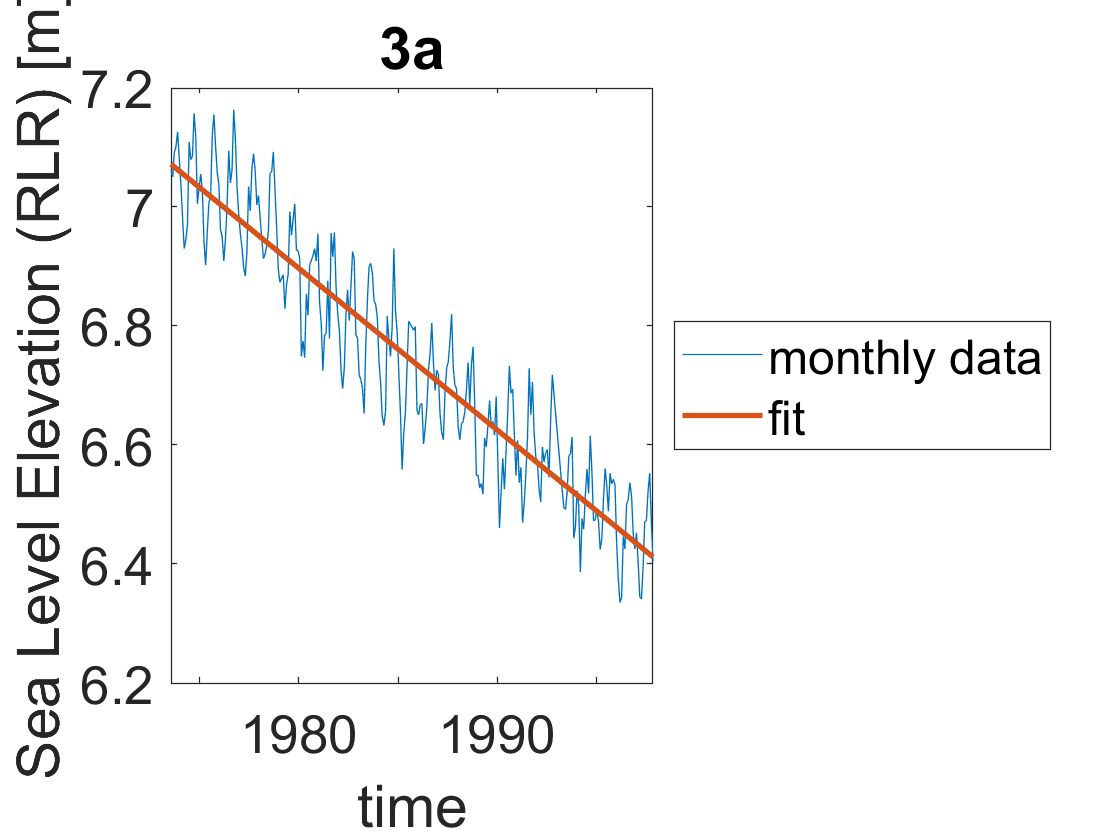

%%3a. Ito II; 16 Jul 1973 to 15 Dec 1997
[date3a, SL3a, date3b, SL3b] = cleave(date3, SL3, datetime(1997, 12, 15));

%%linear regression
num3a = datenum(date3a);
A3a(:, 1) = (num3a - num3a(1))/365;
A3a(:, 2) = 1;
regsol3a = A3a\SL3a;
linreg3a = regsol3a(1).*A3a(:, 1) + regsol3a(2);

plot(date3a, SL3a)
hold on
plot(date3a, linreg3a, 'LineWidth', 2)
set(gca, 'fontsize', 20)
xlabel('time')
ylabel('Sea Level Elevation (RLR) [m]')
title('3a')
legend('monthly data', 'fit', 'location', 'eastoutside')
hold off


%slope of regression [cm/y]
regsol3a(1)*100

ans = -2.7062

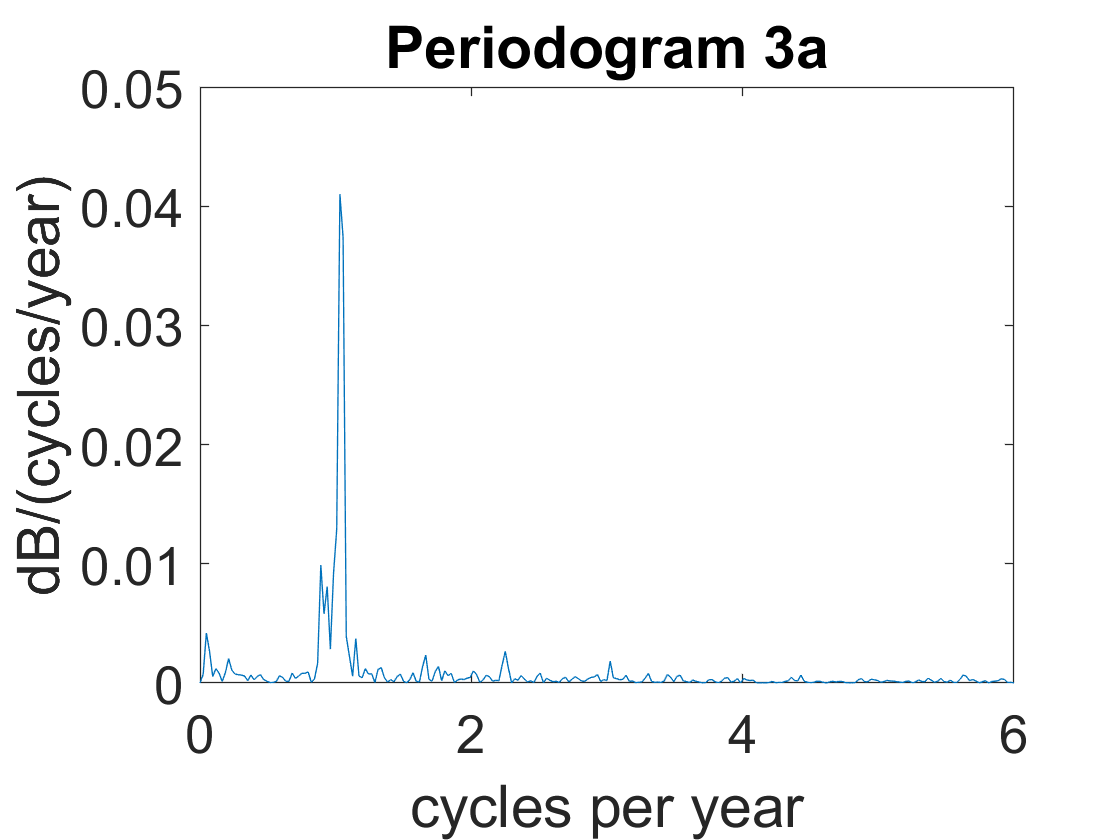


%%periodogram
%normalize data from trend
SL_noSLR3a = SL3a - linreg3a;

%PSD calcs
[pxx3a, f3a] = periodogram(SL_noSLR3a, [], [], 12);

plot(f3a, pxx3a)
set(gca, 'fontsize', 20)
title('Periodogram 3a')
xlabel('cycles per year')
ylabel('dB/(cycles/year)')

%%3b. Ito II; 15 Jan 1999 to 15 Dec 2020
%there is a skip between 1997 and 1999

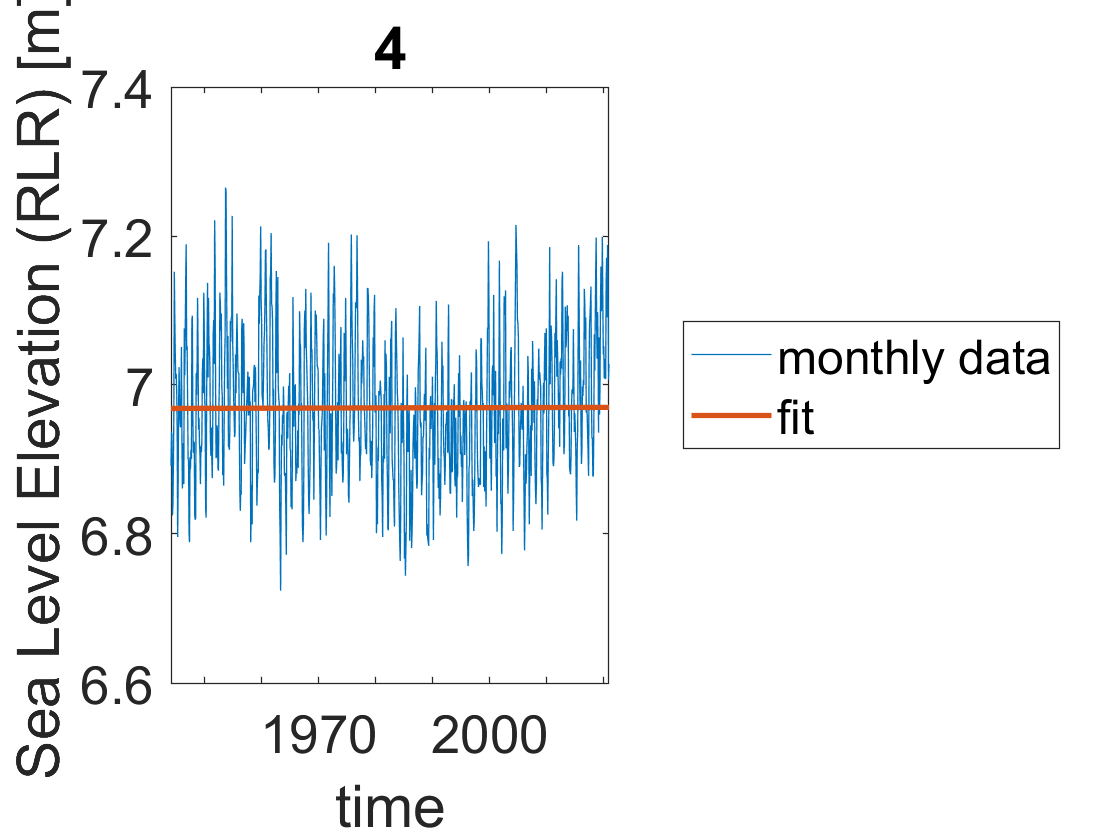

%4. Uchiura
[date4, SL4] = readGauge(path4);

%%linear regression
num4 = datenum(date4);
A4(:, 1) = (num4 - num4(1))/365;
A4(:, 2) = 1;
regsol4 = A4\SL4;
linreg4 = regsol4(1).*A4(:, 1) + regsol4(2);

plot(date4, SL4)
hold on
plot(date4, linreg4, 'LineWidth', 2)
set(gca, 'fontsize', 20)
xlabel('time')
ylabel('Sea Level Elevation (RLR) [m]')
title('4')
legend('monthly data', 'fit', 'location', 'eastoutside')
hold off


%slope of regression [cm/y]
regsol4(1)*100

ans = 0.0018

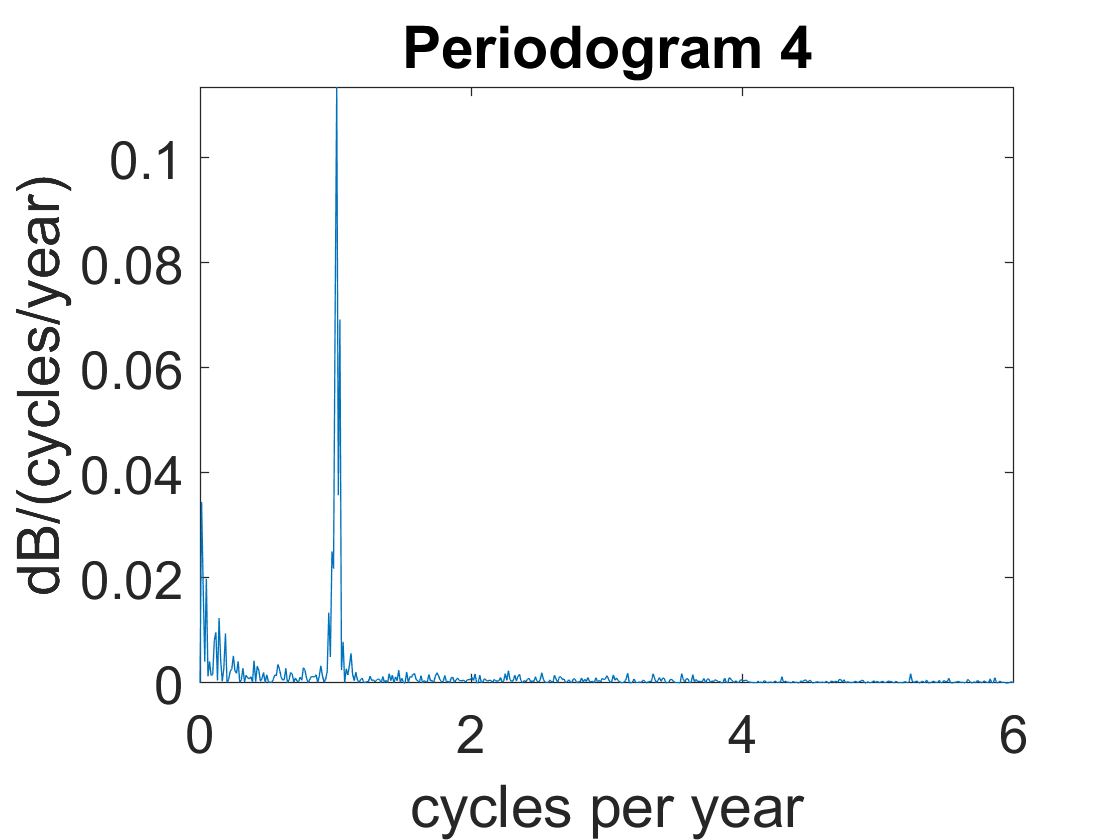


%%periodogram
%normalize data from trend
SL_noSLR4 = SL4 - linreg4;

%PSD calcs
[pxx4, f4] = periodogram(SL_noSLR4, [], [], 12);

plot(f4, pxx4)
set(gca, 'fontsize', 20)
title('Periodogram 4')
xlabel('cycles per year')
ylabel('dB/(cycles/year)')

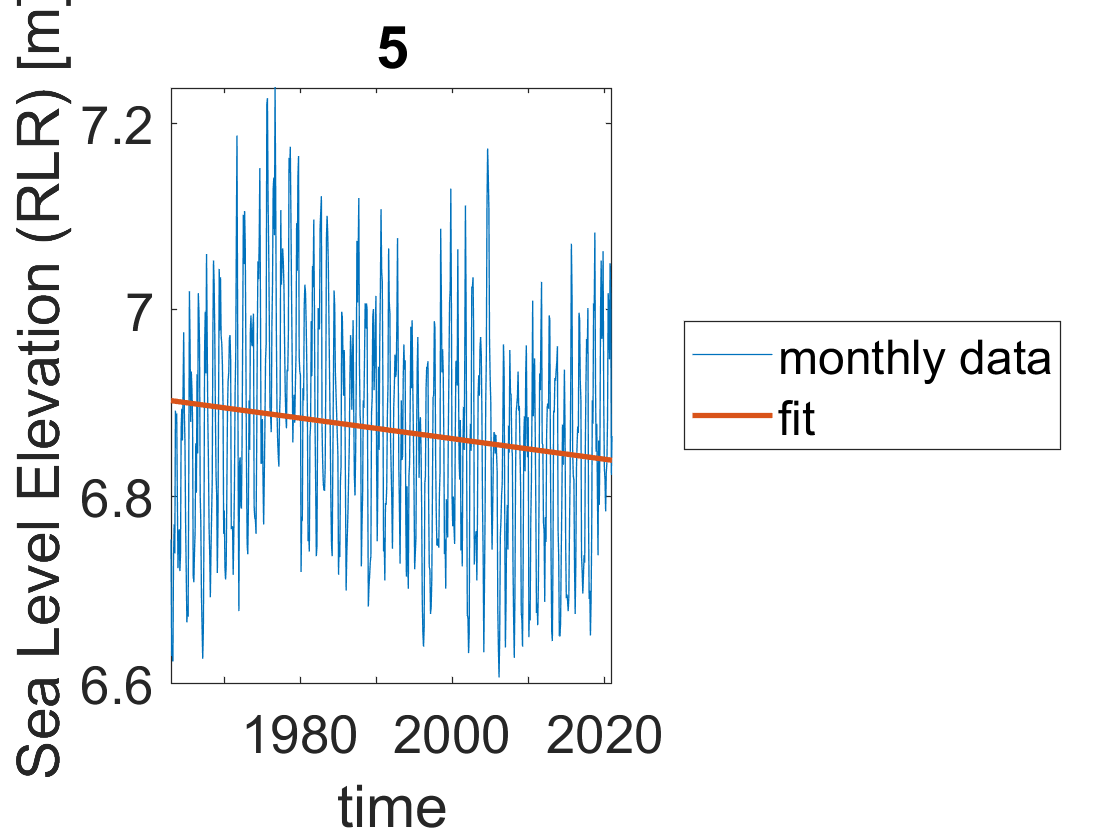

%5. Onisaki
[date5, SL5] = readGauge(path5);

%%linear regression
num5 = datenum(date5);
A5(:, 1) = (num5 - num5(1))/365;
A5(:, 2) = 1;
regsol5 = A5\SL5;
linreg5 = regsol5(1).*A5(:, 1) + regsol5(2);

plot(date5, SL5)
hold on
plot(date5, linreg5, 'LineWidth', 2)
set(gca, 'fontsize', 20)
xlabel('time')
ylabel('Sea Level Elevation (RLR) [m]')
title('5')
legend('monthly data', 'fit', 'location', 'eastoutside')
hold off


%slope of regression [cm/y]
regsol5(1)*100

ans = -0.1103

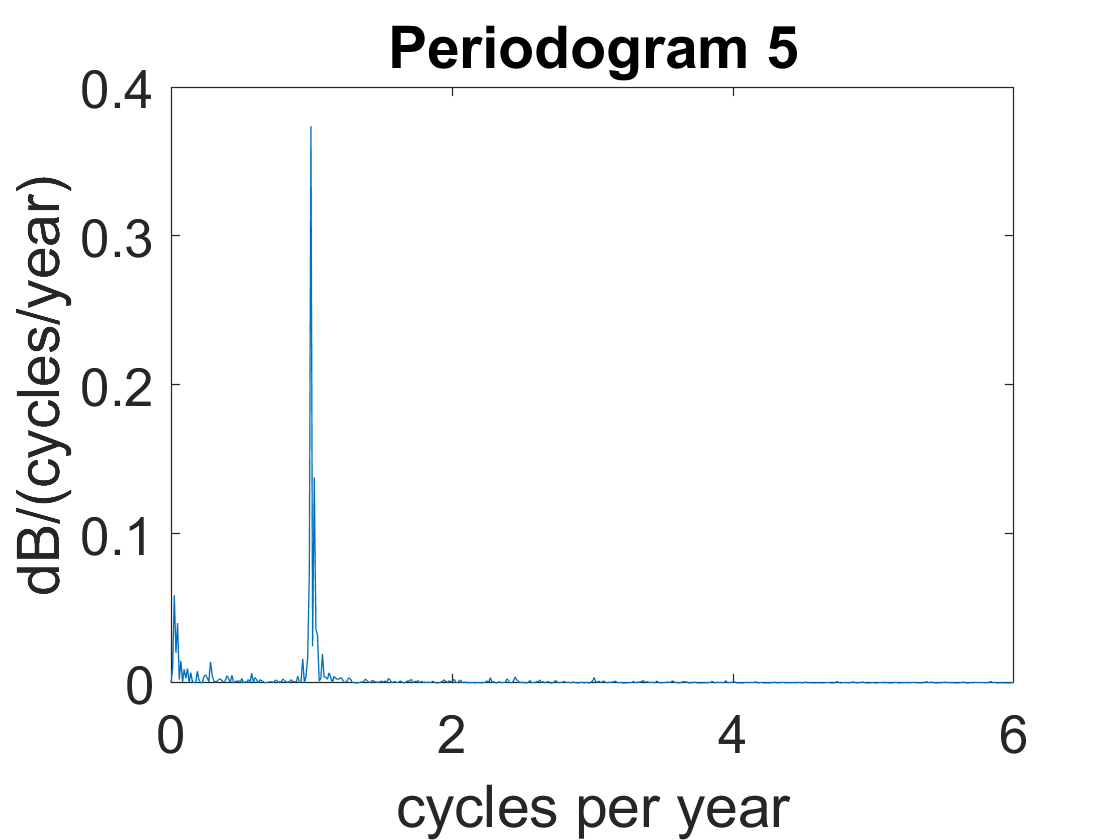


%%periodogram
%normalize data from trend
SL_noSLR5 = SL5 - linreg5;

%PSD calcs
[pxx5, f5] = periodogram(SL_noSLR5, [], [], 12);

plot(f5, pxx5)
set(gca, 'fontsize', 20)
title('Periodogram 5')
xlabel('cycles per year')
ylabel('dB/(cycles/year)')

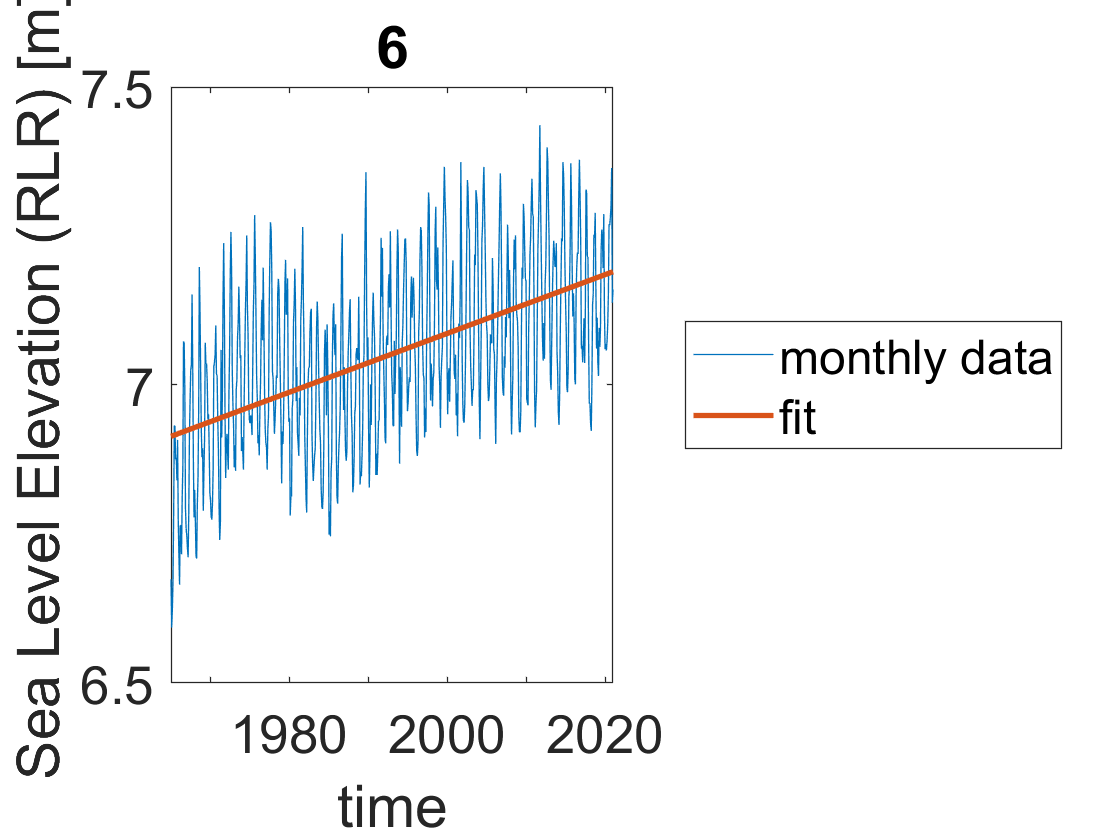

%6. Osaka
[date6, SL6] = readGauge(path6);

%%linear regression
num6 = datenum(date6);
A6(:, 1) = (num6 - num6(1))/365;
A6(:, 2) = 1;
regsol6 = A6\SL6;
linreg6 = regsol6(1).*A6(:, 1) + regsol6(2);

plot(date6, SL6)
hold on
plot(date6, linreg6, 'LineWidth', 2)
set(gca, 'fontsize', 20)
xlabel('time')
ylabel('Sea Level Elevation (RLR) [m]')
title('6')
legend('monthly data', 'fit', 'location', 'eastoutside')
hold off


%slope of regression [cm/y]
regsol6(1)*100

ans = 0.4938

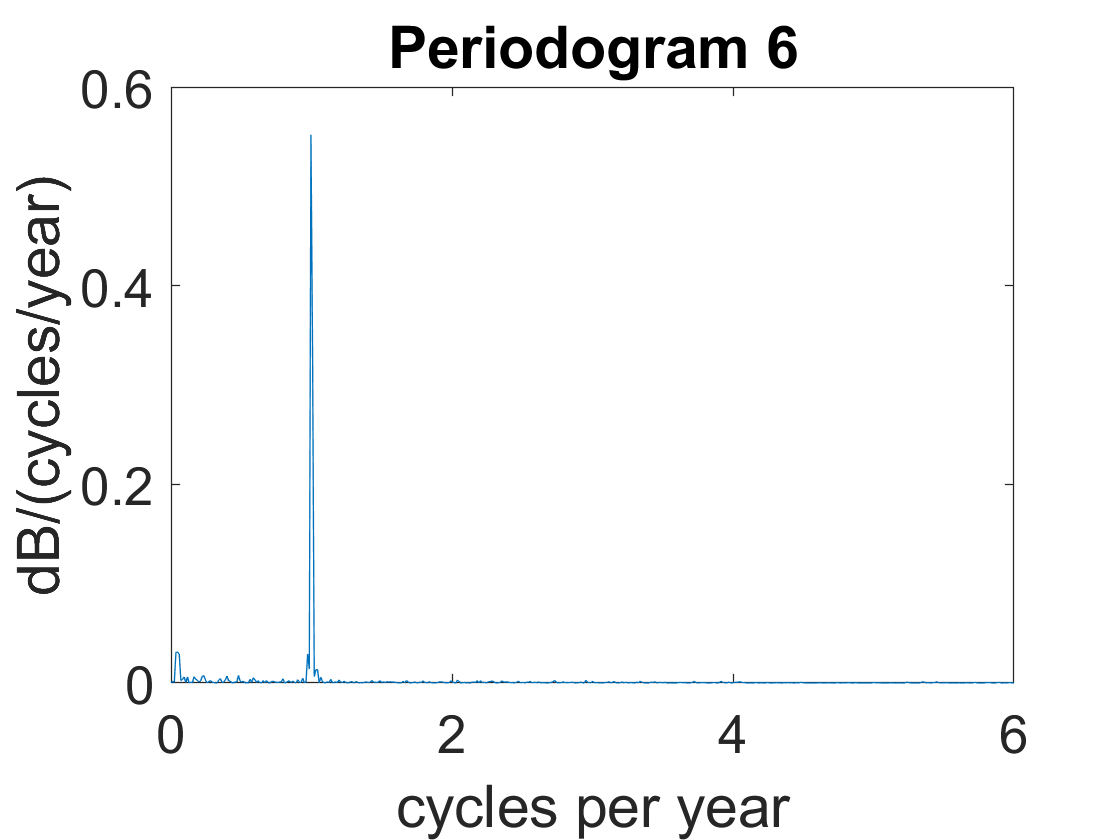


%%periodogram
%normalize data from trend
SL_noSLR6 = SL6 - linreg6;

%PSD calcs
[pxx6, f6] = periodogram(SL_noSLR6, [], [], 12);

plot(f6, pxx6)
set(gca, 'fontsize', 20)
title('Periodogram 6')
xlabel('cycles per year')
ylabel('dB/(cycles/year)')

function [date, SL] = readGauge(path)
%takes data from PSMSL and outputs dates corresponding to SL

%read data
read = readtable(path);
raw = table2array(read);

date = num2cell(ones(size(raw)));
SL = num2cell(ones(size(raw)));

%take out date and SL data
for i = 1:length(raw)
    strings = split(raw{i}, ';');
    date(i) = strings(1);
    SL(i) = strtrim(strings(2));
end

%convert to double
date = str2double(date);
SL = str2double(SL);

%remove null SL
null_ind = SL == -99999;
date(null_ind) = [];
SL(null_ind) = [];

%convert date to datetime
year = floor(date);
secs = (date - year).*(365 + isleapyr(year)).*24.*3600;
date = datetime(year, 1, 0, 0, 0, secs);

%SL to m
SL = SL/1000;
end

function [] = analyze()

function [date_beg, SL_beg, date_end, SL_end] = cleave(inDate, inSL, separator)
%returns data from beginning to separator date, inclusive, and the rest
ind = inDate <= separator;

%returns beginning
date_beg = inDate(ind);
SL_beg = inSL(ind);

%returns end
date_end = inDate(~ind);
SL_end = inSL(~ind);
end

function is = isleapyr(yr)
%  returns T for input year being a leapyear
%  dpbozarth       Rev 0   07Jun1998  Initial
%                  Rev 1   31Mar2005  Use eomday() vs number days in year
%                  Rev 2   04Feb2015  Handle new datetime class
if isdatetime(yr), yr=year(yr); end
is=eomday(yr,2)==29;
end